We create two vectors for data about the population of China. The first has the years of census data, the other has the numbers of millions of people.

year = (1980:10:2010)'  

year =         1980
        1990
        2000
        2010


pop = [984.736; 1148.364; 1263.638; 1330.141];

It's convenient to measure time in years since 1980.

t = year - 1980;
y = pop;

Now we have four data points $(t_1,y_1),\ldots,(t_4,y_4)$, so $n=4$ and we seek an interpolating cubic polynomial. We construct the associated Vandermonde matrix: 

V = zeros(4,4);
for i = 1:4
    V(i,:) = [1 t(i) t(i)^2 t(i)^3];
end
V

V =            1           0           0           0
           1          10         100        1000
           1          20         400        8000
           1          30         900       27000


To solve for the vector of polynomial coefficients, we use a backslash:

c = V \ y

c =    9.8474e+02
   1.8767e+01
  -2.3969e-01
  -6.9500e-05


The algorithms used by the backslash operator are the main topic of this chapter. For now, observe that the coefficients of the cubic polynomial vary over several orders of magnitude, which is typical in this context. By our definitions, these coefficients are given in ascending order of power in $t$. MATLAB always expects the decreasing-degree order, so we convert ours to this convention here.

c = c(end:-1:1);       % reverse the ordering

We can use the resulting polynomial to estimate the population of China in 2005:

polyval(c,2005-1980)   % apply the 1980 time shift

ans =    1.3030e+03


The official figure is 1297.8, so our result is not bad. 

We can visualize the interpolation process. First, we `plot` the data as points. We'll shift the t variable back to actual years. 

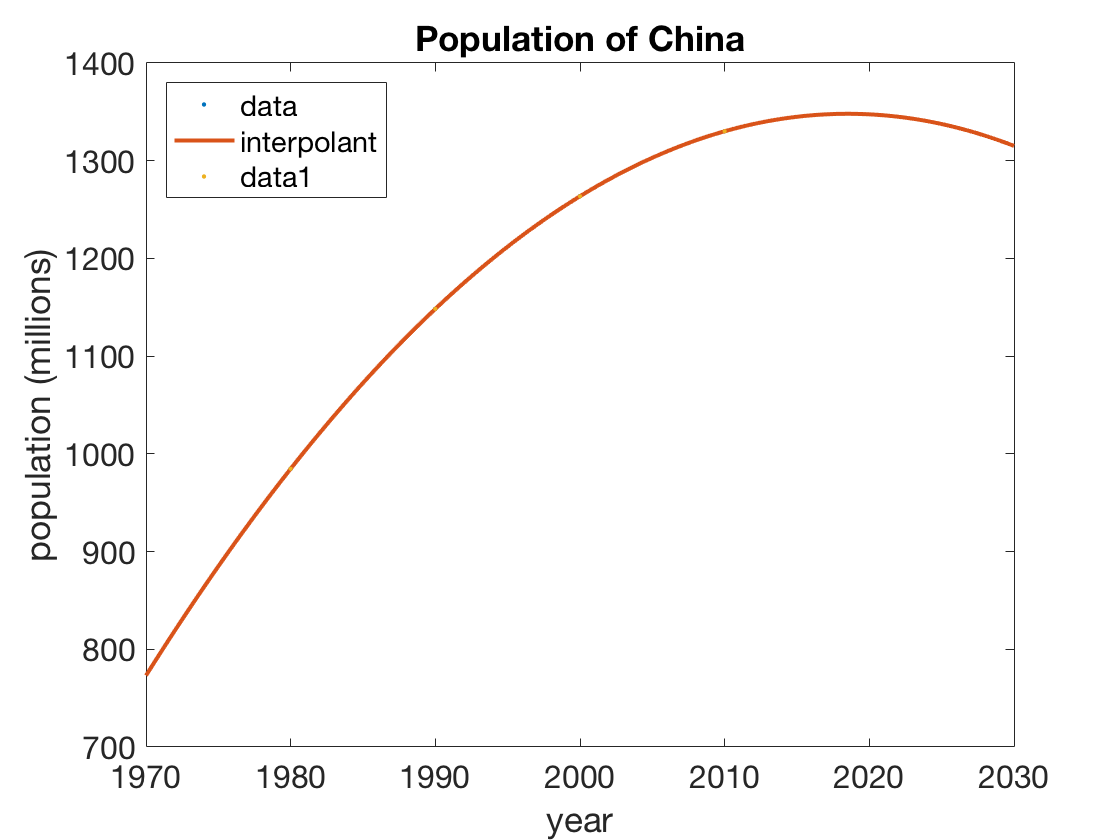

plot(1980+t,y,'.')

We want to superimpose a plot of the polynomial. In order to add to a plot, we must use the `hold` command:

hold on

To plot the interpolating polynomial, we create a vector with many points in the time interval using `linspace`.

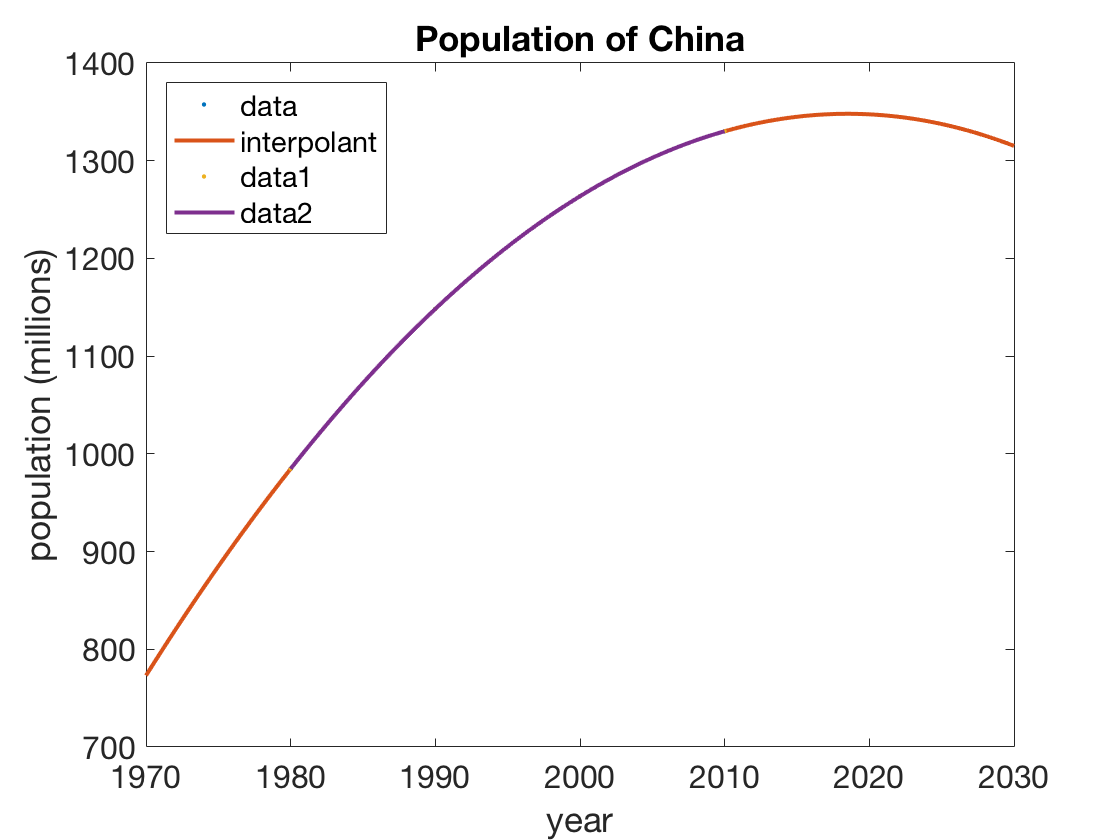

tt = linspace(0,30,300)';   % 300 times from 1980 to 2010
yy = polyval(c,tt);         % evaluate the cubic
plot(1980+tt,yy)

Let's clear the figure (`clf`) and redo it, this time continuing the curve outside of the original date range. We'll also annotate the graph (using `title`, `xlabel`, `ylabel` and `legend`) to make its purpose clear.

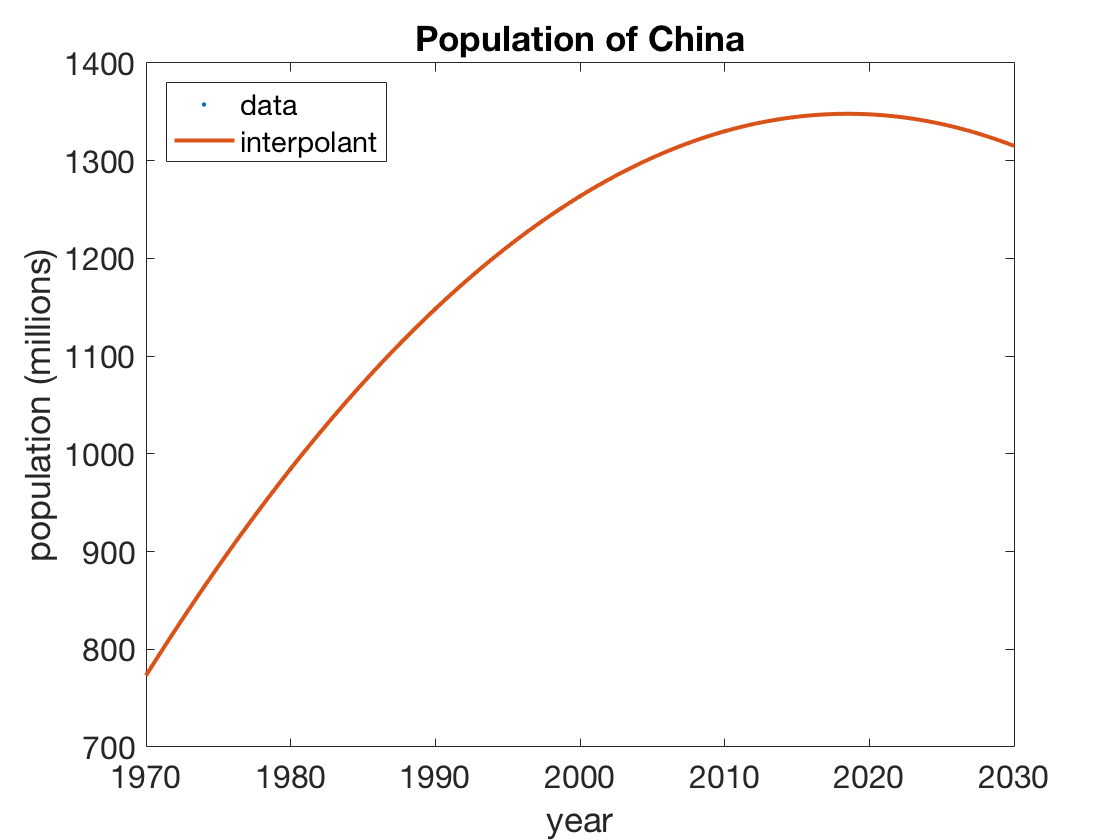

clf   % clear figure
plot(1980+t,y,'.')
hold on
tt = linspace(-10,50,300)';   
plot(1980+tt,polyval(c,tt))
title('Population of China')
xlabel('year'), ylabel('population (millions)')
legend('data','interpolant','location','northwest')

While the interpolation is plausible, the extrapolation to the future is highly questionable! As a rule, extrapolation more than a short distance beyond the original interval is not reliable.